# Reconstruction from Anomalous Trichromatic Mosaic

## Construct retinal mosaic

% See "imageRecon.mlx" for basic reconstruction routine
% Setup constant
display = displayCreate('CRT12BitDisplay');
prior   = load('sparsePrior.mat');

imageSize = [100, 100, 3];

% Create a cone mosaic
retina = ConeResponse('eccBasedConeDensity', true, 'eccBasedConeQuantal', true, ...
    'fovealDegree', 0.80, 'pupilSize', 2.0, 'integrationTime', 0.01);

Create cone moasic object: 
Will do 3 passes
[PASS:  0/ 0]. Adjusting cones between 0.00 180.00 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustment: on iteration 3 ... 
Hex grid adjustment: on iteration 4 ... 
Hex grid adjustment: on iteration 5 ... 
Hex grid adjustment: on iteration 6 ... 
Hex grid adjustment: on iteration 7 ... 
Hex grid adjustment: on iteration 8 ... 
Hex grid adjustment: on iteration 9 ... 
Hex grid adjustment: on iteration 10 ... 
Hex grid smoothing finished.
Did not converge, but exceeded max number of iterations (10).
Max(movement) in last iteration: 0.524645, Tolerange: 0.001000
Number of Delaunay triangulations: 11
[PASS:  1/ 3]. Adjusting cones between 180.00 181.95 using posDiffTolerange: 0.200000

Hex grid adjustment: on iteration 0 ... 
Hex grid adjustment: on iteration 1 ... 
Hex grid adjustment: on iteration 2 ... 
Hex grid adjustm

## Load image data

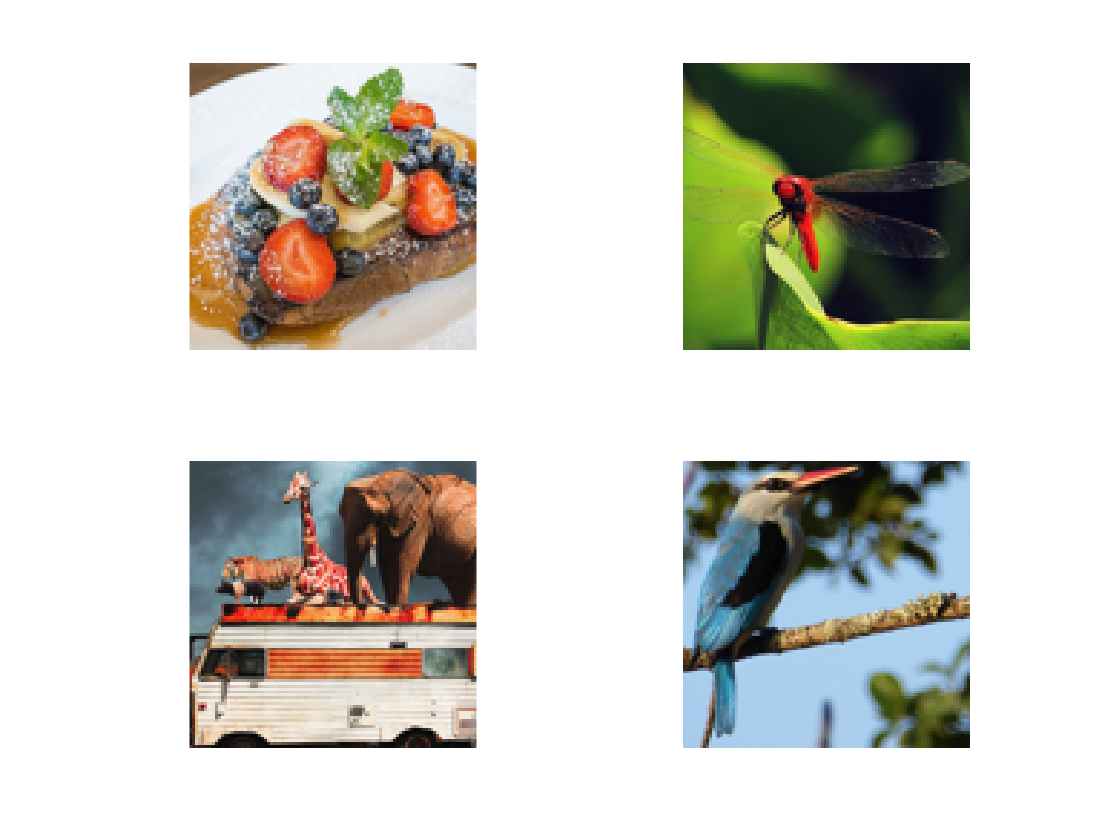

%% Load images
nImage = 4;
input = zeros([nImage, imageSize]);

figure();
fileType = '.jpeg';
for idx = 1:nImage
    fileName = strcat(num2str(idx), fileType);
    filePath = fullfile('.', 'images', fileName);
    image = imresize(im2double(imread(filePath)), 0.30);
    
    image = sampleImage(image, imageSize(1));
    image = image - min(image(:));
    image = image ./ max(image(:));
    
    subplot(2, 2, idx)
    imshow(image, 'InitialMagnification', 400);
    [~, ~, linearImage] = retina.compute(image);
    input(idx, :, :, :) = linearImage;
end

## Render matrix (i.e., likelihood function) for both normal and anomalous observer

renderNormal = retina.forwardRender(imageSize, false, true, false);
renderNormal = double(renderNormal);

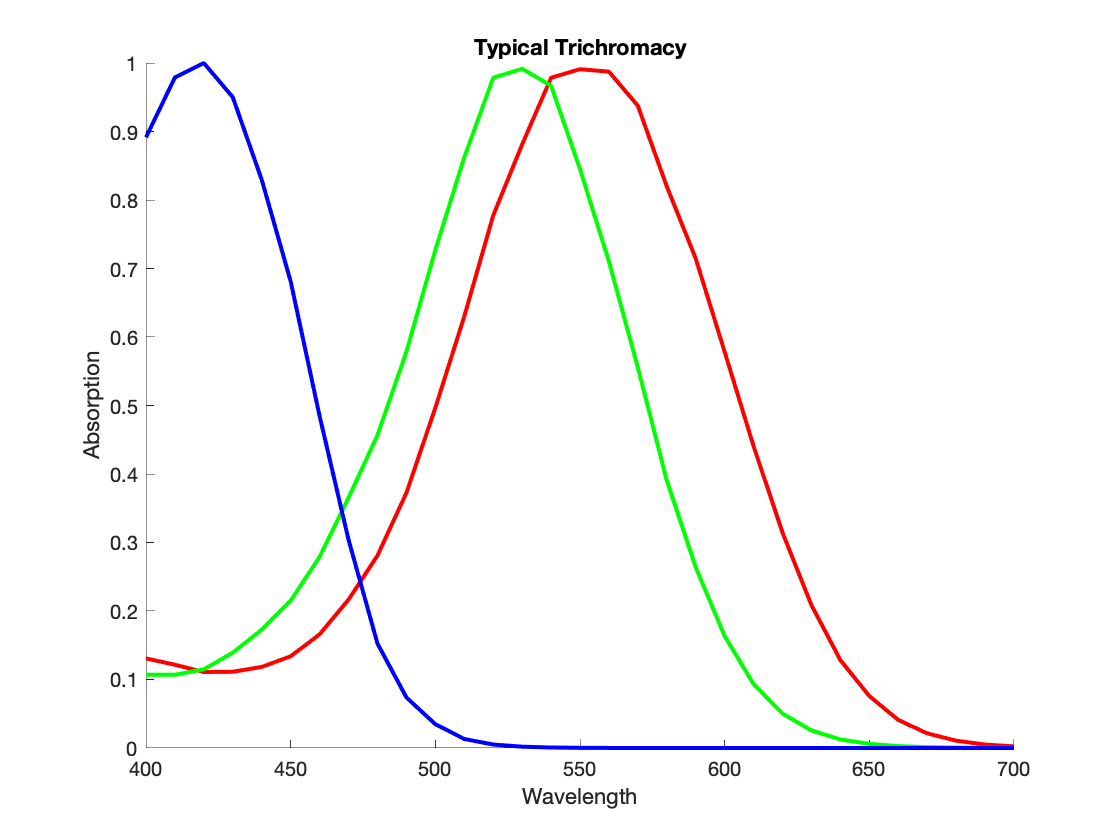

% Plot spectral sensitivity
% get the pigment object
pigment = retina.Mosaic.pigment;

figure(); hold on;
colorSeq = ['r', 'g', 'b'];
for idx = 1 : length(colorSeq)
    % plot absorbance against wavelength
    plot(pigment.wave, pigment.absorbance(:, idx), 'LineWidth', 2, 'Color', colorSeq(idx));
end

xlabel('Wavelength');
ylabel('Absorption');
title('Typical Trichromacy');
grid off; box off;

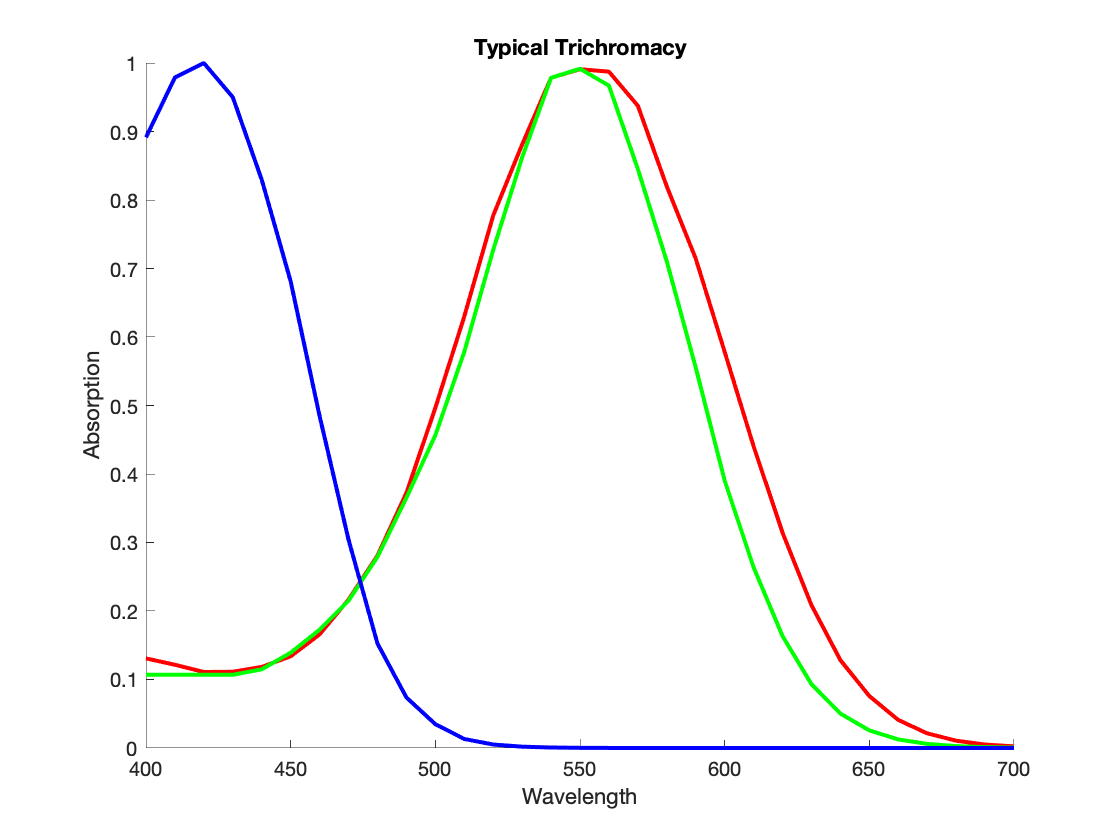

% Shift M cone spectral sensitivity

% Since the step size for wavelength is 10 nm,
% a index displacement of 2 equals a 20 nm shift
% on the wavelength axis

shift = 2;
mCone = pigment.absorbance(:, 2);
anomMcone = pigment.absorbance(:, 2);

anomMcone(1+shift : end) = mCone(1 : end-shift);
anomMcone(1 : shift) = mCone(1 : shift);

% assign the new spectral sensitivity to pigment object
retina.Mosaic.pigment.absorbance(:, 2) = anomMcone;

% plot
pigment = retina.Mosaic.pigment;

figure(); hold on;
colorSeq = ['r', 'g', 'b'];
for idx = 1 : length(colorSeq)
    % plot absorbance against wavelength
    plot(pigment.wave, pigment.absorbance(:, idx), 'LineWidth', 2, 'Color', colorSeq(idx));
end

xlabel('Wavelength');
ylabel('Absorption');
title('Typical Trichromacy');
grid off; box off;

renderAnomalous = retina.forwardRender(imageSize, false, true, false);
renderAnomalous = double(renderAnomalous);

## Reconstruction with trichromatic observer

% Run reconstruction
% note that we are simulating low light/small SNR situation to 
% highlight the difference between normal and anomalous observer

constant = ...
    struct('display', display, 'prior', prior, 'regPara', 0.001, ...
    'imageSize', imageSize, 'nIter', 1e3, 'noise', true);

output = runRecon(renderNormal, input, constant);


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



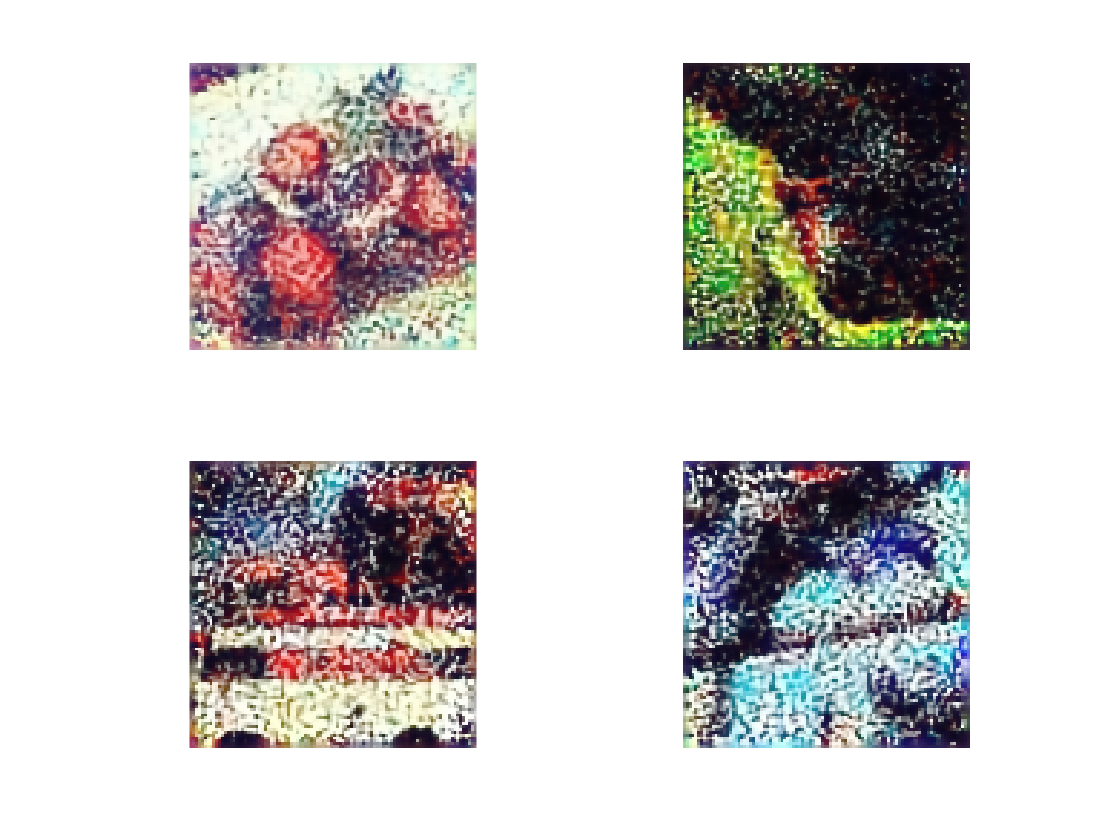

% Show results
figure();
for idx = 1:nImage
    subplot(2, 2, idx);
    imshow(reshape(output(idx, :, :, :), imageSize), 'InitialMagnification', 400);
end

## Reconstruction with anomalous trichromatic observer

output = runRecon(renderAnomalous, input, constant);


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



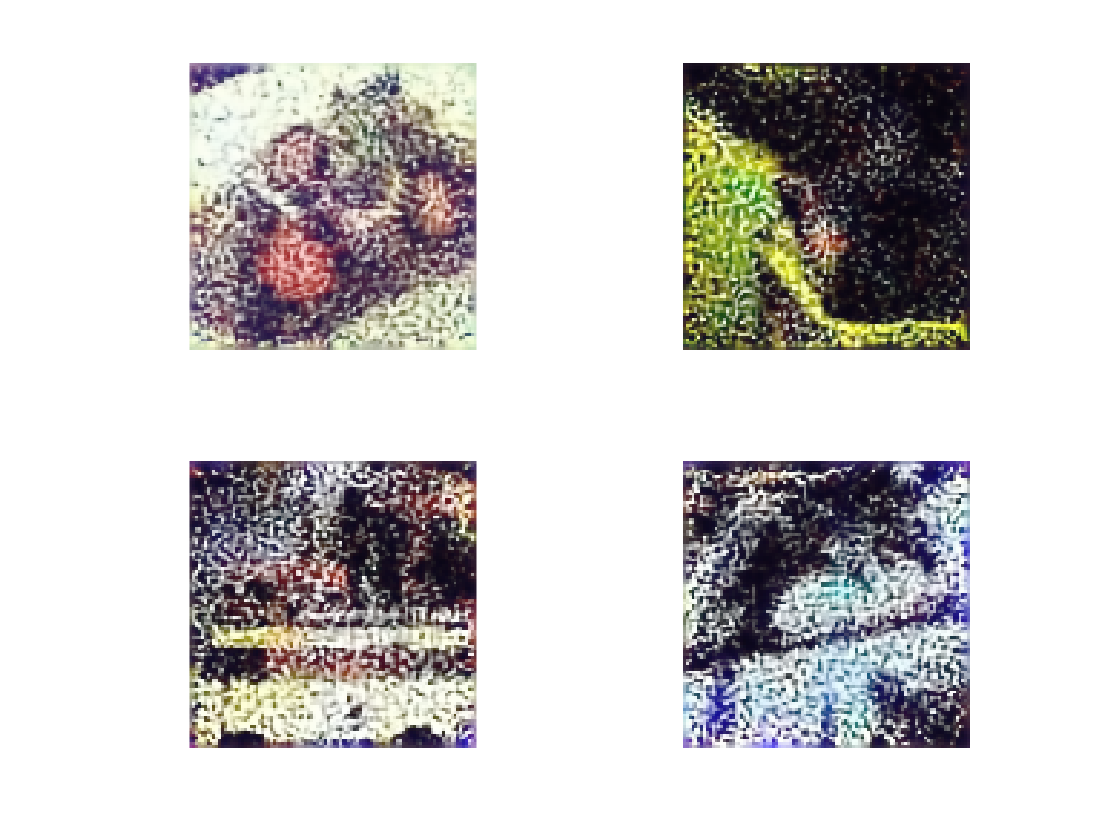

% Show results
% reduced chromatic contrast in color anomalous observer
figure();
for idx = 1:nImage
    subplot(2, 2, idx);
    imshow(reshape(output(idx, :, :, :), imageSize), 'InitialMagnification', 400);
end

## Without noise, chromatic information can be fully reconstructed for anomalous trichromacy

% i.e., anomalous trichromacy can be fully compensated by 
% an ideal observer when SNR is high

constant.noise = false;
constant.regPara = 1e-4;
output = runRecon(renderAnomalous, input, constant);


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+03.



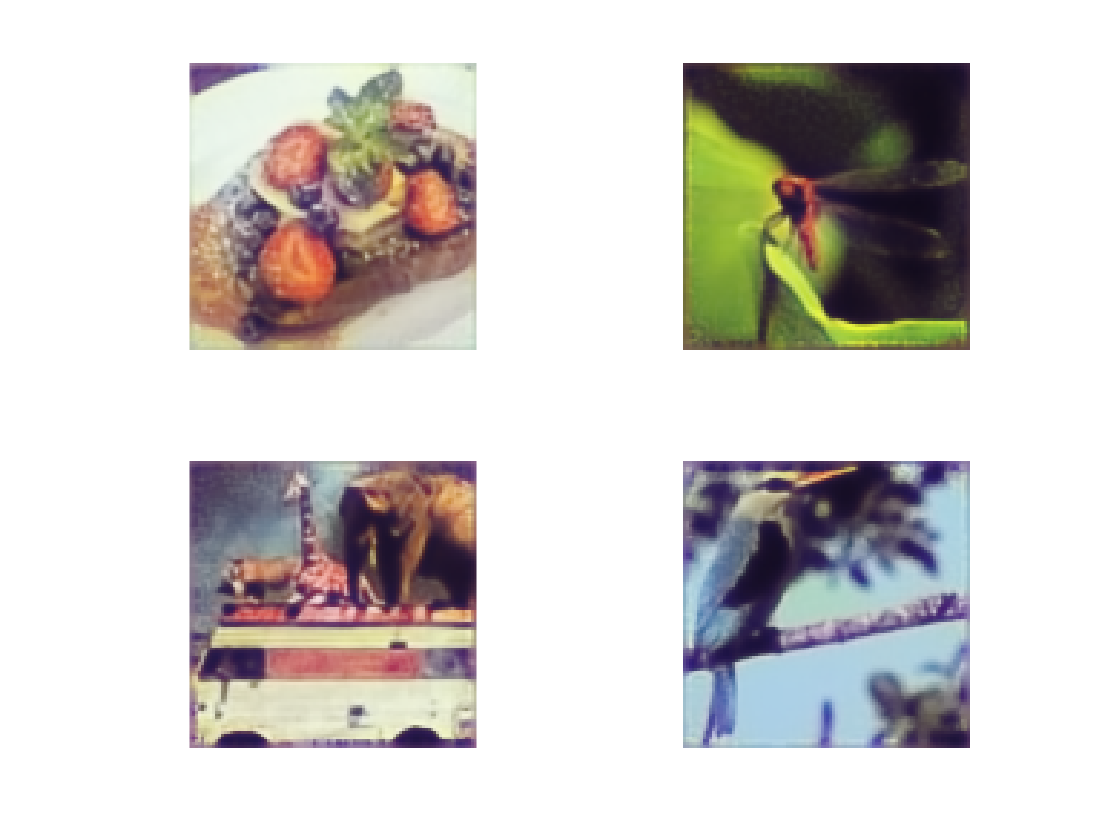

% Show results
figure();
for idx = 1:nImage
    subplot(2, 2, idx);
    imshow(reshape(output(idx, :, :, :), imageSize), 'InitialMagnification', 400);
end

## Helper function for reconstruction

function output = runRecon(render, input, constant)
estimator = ...
    PoissonSparseEstimator(render, inv(constant.prior.regBasis), ...
    constant.prior.mu', constant.regPara, 4, constant.imageSize);

output = zeros(size(input));
parfor idx = 1:size(input, 1)
    image = input(idx, :, :, :);    
    resp  = render * image(:);
    if constant.noise
        resp  = poissrnd(resp);
    end
    
    recon = estimator.estimate(resp, constant.nIter, rand([prod(constant.imageSize), 1]), true, 1.0, 'final');
    output(idx, :, :, :) = gammaCorrection(recon, constant.display);
end
end